error_benign =     0.5031    0.5109    0.9312    0.7132    0.2290    0.1775    0.5081    0.2503


optrank_b = 3

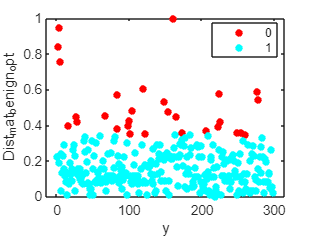

error_malignant =     0.2951    0.3940    0.2038    0.5643    1.0888    1.9636    0.3894    0.3012


optrank_m = 6

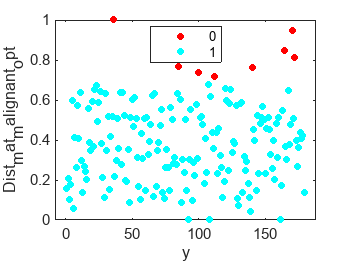

error_benign =     0.3446    0.3663    0.6290    0.5864    0.9273    0.1944    0.3671    0.4424


optrank_b = 5

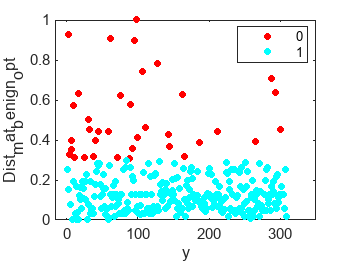

error_malignant =     2.4059    1.7174    0.5485    0.6336    0.6077    0.2941    1.0077    0.8589


optrank_m = 1

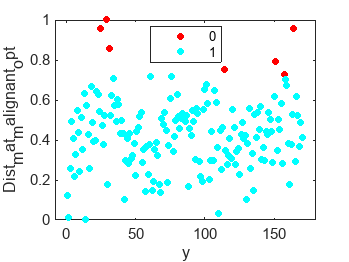

error_benign =     0.5200    1.0623    0.4612    0.9554    0.4818    0.4715    0.5224    0.4455


optrank_b = 2

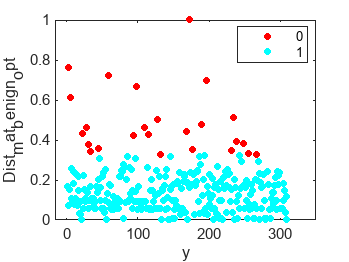

error_malignant =     2.1561    1.7578    0.9927    0.8999    0.6470    0.6537    0.4476    0.3262


optrank_m = 1

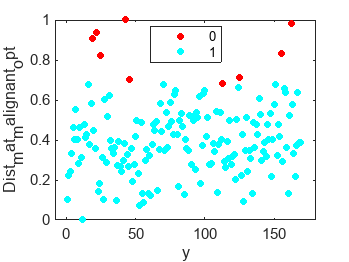

error_benign =     0.3639    0.5301    0.4045    0.6276    0.9826    0.3147    0.3946    0.5364


optrank_b = 5

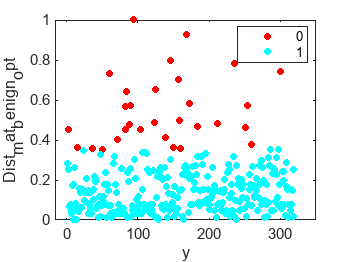

error_malignant =     1.9140    1.9744    0.4065    1.4622    1.7165    1.3663    0.2678    0.5796


optrank_m = 2

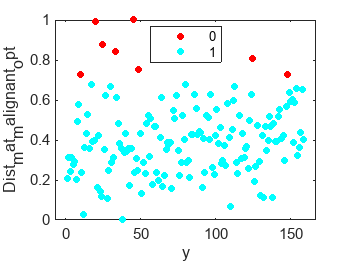

error_benign =     0.4526    0.7548    0.4367    0.3560    0.5974    0.4510    0.2187    0.4150


optrank_b = 2

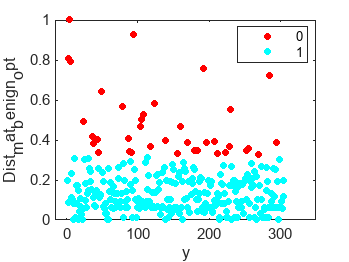

error_malignant =     1.8166    0.7038    0.0211    1.4863    0.8616    0.5945    0.3011    0.3023


optrank_m = 1

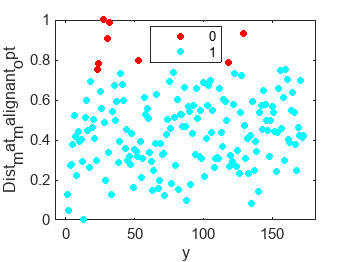

error_benign =     0.3148    0.4014    0.3549    0.5445    0.4479    0.1812    0.3740    0.3291


optrank_b = 4

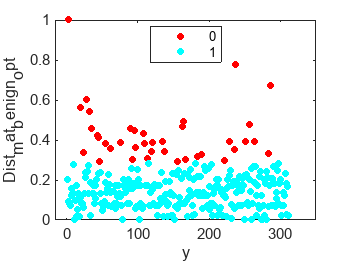

error_malignant =     0.7132    0.9323    0.5877    1.2996    0.4371    0.5241    1.1491    0.1716


optrank_m = 4

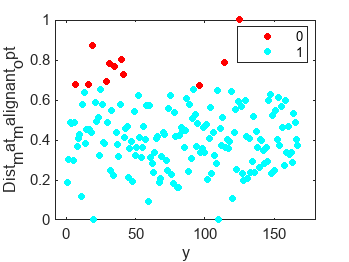

error_benign =     0.4271    0.5842    0.6566    0.9957    0.5190    0.8819    3.2283    0.2832


optrank_b = 7

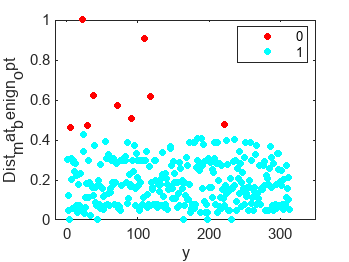

error_malignant =     1.4958    0.6075    1.2902    0.8395    0.6540    1.2287    0.3054    0.6906


optrank_m = 1

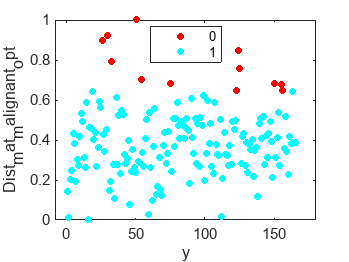

error_benign =     0.4258    0.6345    0.3640    0.8770    1.3703    0.3811    0.2544    0.2853


optrank_b = 5

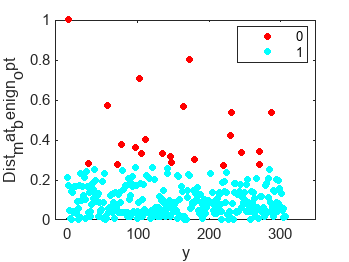

error_malignant =     1.8843    0.6769    0.3617    0.7597    0.6585    0.7243    1.0360    0.7252


optrank_m = 1

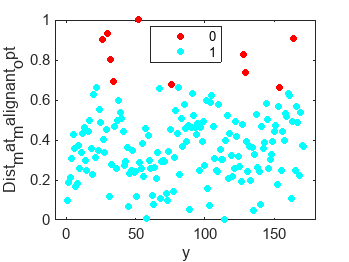

error_benign =     0.3559    0.6752    0.6844    0.7780    1.3347    1.1792    0.5110    0.7376


optrank_b = 5

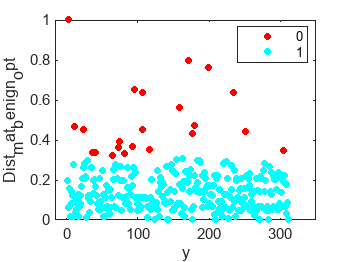

error_malignant =     2.7992    1.2405    0.9971    0.3793    0.1186    0.6540    0.2602    0.5940


optrank_m = 1

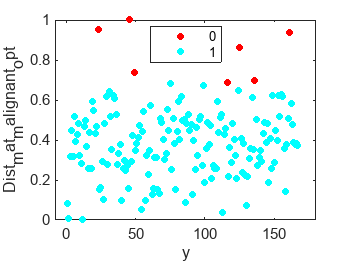

error_benign =     1.1058    1.2498    1.1841    1.0308    0.9977    1.0266    0.2990    0.3032


optrank_b = 2

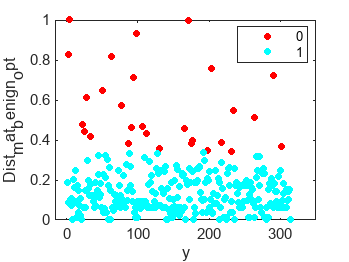

error_malignant =     1.8319    1.8897    0.4443    0.7739    0.4511    0.4978    0.9260    1.8197


optrank_m = 2

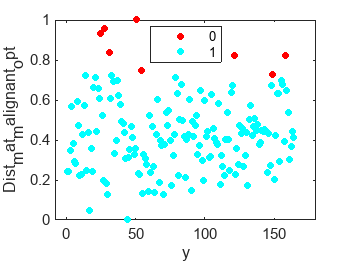

for j = [1,2,3,4,5,6,7,8,9,10]
    figure

    splitfolder=strcat('split',num2str(j));
    per =[10];%[50,40,30,20,10,5,2,0];
    for percent = per
        cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
        cd (splitfolder)

        folder=strcat('per',num2str(percent));
        cd (folder)
        my_file = strcat('cell_sample_noisy_per_',num2str(percent),'.csv');
        File=readmatrix(my_file,"NumHeaderLines",1);

        benign=File(File(:,10)==2,1:9);
        T_benign=benign.';
        malignant=File(File(:,10)==4,1:9);
        T_malignant=malignant.';

        folder_l1=strcat('ACE_dist_8optrank_angle_l1pca_per',num2str(percent));
        mkdir (folder_l1)

        ranks=[1,2,3,4,5,6,7,8];

        error_benign = nan(size(ranks));
        numbenign=length(T_benign);
        Dist_mat_benign_array=nan(length(ranks),numbenign);
        threshold_rank_b=nan(size(ranks));
        elbow_indx_rank_b=nan(size(ranks));

        for i = ranks
            %fprintf("Rank is %i \n", i) %i);
            cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering\

            T_benign_temp=T_benign;
            Dist_mat_benign=[];


            BF_benign=l1pca_BF(T_benign,i,1,10,10,'');
            for k = 1 : numbenign
                A=T_benign(:,k);
                Dist_mat_benign(k)=norm((A-(BF_benign*BF_benign.'*A)),1);
                k;
            end

            min_val=min(Dist_mat_benign,[],"all");
            max_val=max(Dist_mat_benign,[],"all");
            Dist_mat_benign= Dist_mat_benign-min_val;%]/[max_val-min_val]
            Dist_mat_benign=Dist_mat_benign /(max_val-min_val);


            Dist_mat_benign_array(i,:)=Dist_mat_benign;
            [Dist_mat_benign_asc,Indx_b]=sort(Dist_mat_benign,"ascend");


            [elbow_b_err_angle,elbow_indx_b]=knee_pt_angle((Dist_mat_benign_asc));

            error_benign(i)=elbow_b_err_angle;
            threshold_rank_b(i)=Dist_mat_benign_asc(elbow_indx_b);
            elbow_indx_rank_b(i)=elbow_indx_b;

% 
%             figure
%             plot((Dist_mat_benign_asc),'-s',"MarkerIndices",(elbow_indx_b),'MarkerFaceColor','red','MarkerSize',10 )
%             xlabel("index")
%             ylabel(["Distance Benign Asc for Rank",num2str(i)])
%             title(['Rank =',num2str(i) ])


        end

        
        error_benign

        [~,optrank_b]= max(error_benign)

        Dist_mat_benign_opt=Dist_mat_benign_array(optrank_b,:);
        threshold_dist_b= threshold_rank_b(optrank_b);
        elbow_indx_b_opt=elbow_indx_rank_b(optrank_b);

        ind_O_b=find(Dist_mat_benign_opt>threshold_dist_b);
        ind_I_b=find(Dist_mat_benign_opt<=threshold_dist_b);


        cluster_b=zeros(size(Dist_mat_benign_opt));
        cluster_b(ind_I_b)=1;
        figure
        y= 1:1:length(benign);
        numGroups = length(unique(cluster_b));
        gscatter(y,Dist_mat_benign_opt,cluster_b,hsv(numGroups))
% 
%         figure
%         plot(sort(Dist_mat_benign_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_b_opt),'MarkerFaceColor','red','MarkerSize',10 )
%         xlabel("index")
%         ylabel(["Distance Benign Asc for opt rank" ,num2str(optrank_b)])
%         title(['Rank opt for Benign =',num2str(optrank_b),"Split=",num2str(j)])
%         ind_O_b;


        T_benign_temp(:,ind_O_b)=[];
        length(T_benign_temp);

        Final_benign=T_benign_temp';
        Final_benign(:,10)=2;

    end
    %
    %
    %    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    nummalignant=length(T_malignant);
    error_malignant=nan(size(ranks));
    Dist_mat_mal_array=nan(length(ranks),nummalignant);
    threshold_rank_m=nan(size(ranks));
    elbow_rank_m=nan(size(ranks));


    for i=ranks
        %fprintf("Rank is %i \n", i) %i);

        T_malignant_temp=T_malignant;
        Dist_mat_malignant=[];

        BF_malignant=l1pca_BF(T_malignant,i,1,10,10,'');
        for k = 1 : nummalignant
            A=T_malignant(:,k);
            Dist_mat_malignant(k)=norm((A-(BF_malignant*BF_malignant.'*A)),1);
            k;
        end

        Dist_mat_malignant;
        min_val=min(Dist_mat_malignant,[],"all");
        max_val=max(Dist_mat_malignant,[],"all");
        Dist_mat_malignant= Dist_mat_malignant -min_val;%]/[max_val-min_val]
        Dist_mat_malignant=Dist_mat_malignant /(max_val-min_val);
        Dist_mat_mal_array(i,:)=Dist_mat_malignant;

        [Dist_mat_malignant_asc,Indx_m]=sort(Dist_mat_malignant,"ascend");


        [elbow_m_err_angle,elbow_indx_m]=knee_pt_angle((Dist_mat_malignant_asc));

        error_malignant(i)=elbow_m_err_angle;
        threshold_rank_m(i)=Dist_mat_malignant_asc(elbow_indx_m);
        elbow_rank_m(i)=elbow_indx_m;

%         figure
%         plot((Dist_mat_malignant_asc),'-*',"MarkerIndices",(elbow_indx_m),'MarkerFaceColor','red','MarkerSize',10 )
%         xlabel("Index")
%         ylabel("Distance Malignant Asc")
%         title(["Rank =", num2str(i)])


    end
    error_malignant
    [~,optrank_m]= max(error_malignant)

    Dist_mat_malignant_opt=Dist_mat_mal_array(optrank_m,:);
    threshold_dist_m= threshold_rank_m(optrank_m);
    elbow_indx_m_opt=elbow_rank_m(optrank_m);

    ind_O_m=find(Dist_mat_malignant_opt>threshold_dist_m);
    ind_I_m=find(Dist_mat_malignant_opt<=threshold_dist_m);

    cluster_m=zeros(size(Dist_mat_malignant_opt));
    cluster_m(ind_I_m)=1;

    figure
    y= 1:1:length(malignant);
    numGroups = length(unique(cluster_m));
    gscatter(y,Dist_mat_malignant_opt,cluster_m,hsv(numGroups))

%     figure
%     plot(sort(Dist_mat_malignant_opt,"ascend"),'-*',"MarkerIndices",(elbow_indx_m_opt),'MarkerFaceColor','red','MarkerSize',10 )
%     xlabel("Index")
%     ylabel("Distance Malignant Asc for opt rank")
%     title(["Opt Rank for Malignant=",num2str(optrank_m),"Split=",num2str(j)])

    ind_O_m;


    T_malignant_temp(:,ind_O_m)=[];
    length(T_malignant_temp);

    Final_malignant=T_malignant_temp';
    Final_malignant(:,10)=4;


    cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
    cd (splitfolder)
    cd (folder)

    cd (folder_l1)

    L1pca_file=(horzcat(Final_benign.',Final_malignant.')).';

    L1pca_file = array2table(L1pca_file);
    L1pca_file.Properties.VariableNames(1:10)=  {'Clump','UnifSize','UnifShape','MargAdh','SingEpiSize','BareNuc','BlandChrom','NormNucl','Mit','Class'};
    filel1pca=strcat('cell_sample_noisy_per',num2str(percent),'_ACE_l1pca.csv');
    writetable(L1pca_file,filel1pca);

end